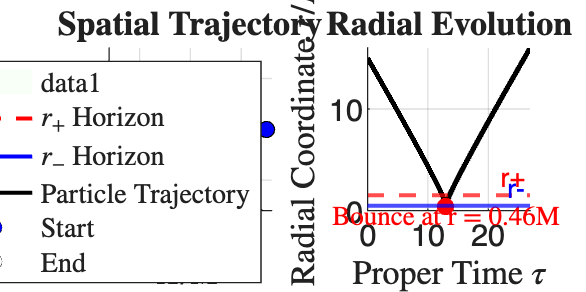

    % RN wormhole的时空旅行
    close all; clc;
    % 设置 LaTeX 解释器
    set(0, 'DefaultTextInterpreter', 'latex');
    set(0, 'DefaultAxesFontSize', 14);

    % 物理参数
    M = 1.0;    % 质量
    Q = 0.85;   % 电荷
    L = 2.0;    % 角动量
    E = 1.4;    % 能量

    % 几何与初始条件 
    r_start = 15.0;
    r_plus  = M + sqrt(M^2 - Q^2);  % 外视界 
    r_minus = M - sqrt(M^2 - Q^2);  % 内视界

    % 初始径向速度计算
    f_s = 1 - 2*M/r_start + Q^2/r_start^2;
    V_s = f_s * (1 + L^2/r_start^2);
    
    if E^2 < V_s
        error('初始能量不足！粒子被挡在有效势垒之外。');
    end
    
    dr0 = -sqrt(E^2 - V_s); % 向内落入
    y0 = [r_start; dr0; 0]; 

    % 数值求解    
    t_span = linspace(0, 150, 8000); 
    opts = odeset('RelTol', 1e-10, 'AbsTol', 1e-12);
    [T, Y] = ode45(@(t,y) equations(t,y,M,Q,L), t_span, y0, opts);

    r_dat = Y(:,1);
    phi_dat = Y(:,3);
    
    % 转换坐标
    x_dat = r_dat .* cos(phi_dat);
    y_dat = r_dat .* sin(phi_dat);

    % 绘图
    figure('Color', 'w', 'Position', [100, 100, 1000, 500], 'Name', 'RN Static Trajectory');

    % 左图：空间轨迹 X-Y 
    ax1 = subplot(1, 2, 1);
    hold(ax1, 'on'); grid(ax1, 'on'); axis(ax1, 'equal');
    
    fill_circle(ax1, 0, 0, r_minus, [0.9 1 0.9]); % 浅绿色
 
    theta = linspace(0, 2*pi, 500);
    plot(ax1, r_plus*cos(theta), r_plus*sin(theta), 'r--', 'LineWidth', 1.5, 'DisplayName', '$r_+$ Horizon');
    plot(ax1, r_minus*cos(theta), r_minus*sin(theta), 'b-', 'LineWidth', 1.5, 'DisplayName', '$r_-$ Horizon');

    % 绘制粒子轨迹
    plot(ax1, x_dat, y_dat, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Particle Trajectory');
    
    % 标记起点和终点
    plot(ax1, x_dat(1), y_dat(1), 'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Start');
    plot(ax1, x_dat(end), y_dat(end), 'ko', 'MarkerFaceColor', 'w', 'DisplayName', 'End');

    xlabel(ax1, '$X / M$'); ylabel(ax1, '$Y / M$');
    title(ax1, '\textbf{Spatial Trajectory}');
    legend(ax1, 'Location', 'northeast', 'Interpreter', 'latex');
    xlim(ax1, [-16 16]); ylim(ax1, [-16 16]);

    % 右图：r-tau图 
    ax2 = subplot(1, 2, 2);
    hold(ax2, 'on'); grid(ax2, 'on');

    % 绘制视界线
    yline(ax2, r_plus, 'r--', 'LineWidth', 1.5, 'Label', 'r+', 'LabelHorizontalAlignment', 'right');
    yline(ax2, r_minus, 'b-', 'LineWidth', 1.5, 'Label', 'r-', 'LabelHorizontalAlignment', 'right');
    
    % 绘制 r 随时间的变化
    plot(ax2, T, r_dat, 'k-', 'LineWidth', 2);
    
    % 标注反弹点 
    [min_r, idx_min] = min(r_dat);
    plot(ax2, T(idx_min), min_r, 'ro', 'MarkerFaceColor', 'r');
    text(ax2, T(idx_min), min_r - 1, sprintf('Bounce at r = %.2fM', min_r), ...
        'HorizontalAlignment', 'center', 'Color', 'r', 'FontWeight', 'bold');

    xlabel(ax2, 'Proper Time $\tau$');
    ylabel(ax2, 'Radial Coordinate $r / M$');
    title(ax2, '\textbf{Radial Evolution}');
    ylim(ax2, [0 16]);




% 画圆填充函数
function fill_circle(ax, x, y, r, c)
    th = linspace(0, 2*pi, 100);
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    fill(ax, xunit, yunit, c, 'EdgeColor', 'none', 'FaceAlpha', 0.3);
end

% 物理方程函数
function dydt = equations(~, y, M, Q, L)
    r = y(1); dr = y(2);
    
    f = 1 - 2*M/r + Q^2/r^2;
    h = 1 + L^2/r^2;
    
    df_dr = 2*M/r^2 - 2*Q^2/r^3;
    dh_dr = -2*L^2/r^3;
    
    dV_dr = df_dr*h + f*dh_dr;
    
    dydt = [dr; -0.5*dV_dr; L/r^2];
end